# Fetching and Displaying Weather data in MATLAB

This MATLAB script retrieves the current weather information for a specified city (Boston) using the Weatherstack API. It demonstrates how to construct an API request URL, fetch data from the web, handle potential errors, extract specific weather details from the fetched data, and display the result in a user-friendly format.

## Timestamp

currentTime = datetime('now')

currentTime = datetime
   06-Aug-2024 11:24:45


## Setup

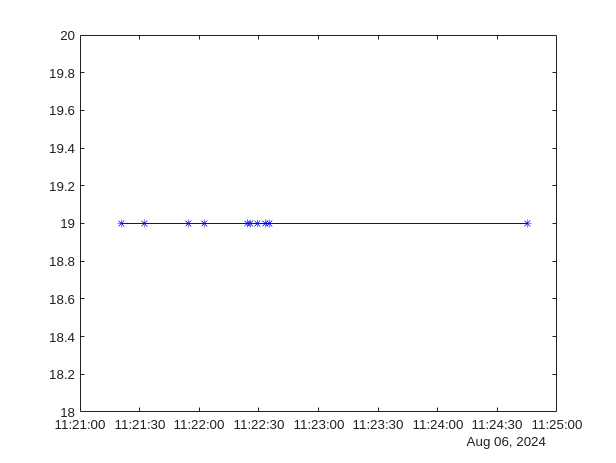

load('responses.mat', 'responses');

% Define your API key (replace with your actual API key)
apiKey = '5551b9fc383c1ea860e30f787162613a';

% Define the city for which you want to get the weather
city = 'Boston';

% Define the URL for the API request
url = sprintf('http://api.weatherstack.com/current?access_key=%s&query=%s', apiKey, city);
% Make the API request and read the response
response = webread(url);

% Check if the API returned an error
if isfield(response, 'error')
    error('Error from Weatherstack API: %s', response.error.info);
end

% Extract relevant information from the response
temperature = response.current.temperature;
weatherDescription = string(response.current.weather_descriptions{1});
humidity = response.current.humidity;
windSpeed = response.current.wind_speed;

newRow = table(currentTime, temperature, weatherDescription, humidity, windSpeed);
responses = [responses; newRow];
save('responses.mat','responses');

plot(responses.currentTime(end-9:end), responses.temperature(end-9:end), 'b*-')

## Display Data

% Display the weather information
currentTime = datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss');
fprintf('Current time in %s:%s\n', city, currentTime);

Current time in Boston:2024-08-06 11:24:45


fprintf('Current weather in %s:\n', city);

Current weather in Boston:


fprintf('Temperature: %.2f°C\n', temperature);

Temperature: 19.00°C


fprintf('Weather: %s\n', weatherDescription);

Weather: Patchy rain nearby


fprintf('Humidity: %d%%\n', humidity);

Humidity: 97%


fprintf('Wind Speed: %.2f km/h\n', windSpeed);

Wind Speed: 13.00 km/h
